# Prediction of Liver Disease in Patients

Note: the comments with "IT. STEP" preceed sections or lines of code we added after we evaluated the model performance, and are part of the iteration step.

## 1: Importing the Data

clear
load dataset.mat

% copy Dataset into a new table variable 
tbl = Dataset; 

% trasform Disease feature into categorical
tbl.Disease = categorical(tbl.Disease);


## 2: Visualization and Considerations

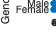

% visualization of each variable, using Gender to make the inspection
% easier. 

scatterhistogram(tbl,"Total_Proteins", "Gender");

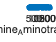


% the dataset in unbalanced: 3:1 ratio of liver: non-liver patients
scatterhistogram(tbl,"Alamine_Aminotransferase", "Disease");

### 2.1: IT. STEP Liver vs Non-Liver Patients' Features

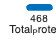


% The model perfomed poorly, especially on non-liver patients. 
% We think this is in part due to the nature of the (unbalanced) dataset,
% where the non-liver patients have features that are, in most cases,
% very similar to liver patients.
scatterhistogram(tbl,"Total_Proteins", "Disease");

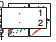


% UNCOMMENT to produce multiple figures 
%{
contvars = ["Total_Bilirubin", "Direct_Bilirubin", "Alkaline_Phosphotase", "Alamine_Aminotransferase", "Aspartate_Aminotransferase", "Total_Proteins", "Albumin", "Albumin_and_Globulin_Ratio"];
for i=1:length(contvars)
    for j=1+i:length(contvars)
        %subplot((length(contvars)/2),2,i)
        figure();
        gscatter(eval(strcat("tbl.",contvars(i))), eval(strcat("tbl.",contvars(j))), tbl.Disease)
        xlabel(contvars(i))
        ylabel(contvars(j))
        title(contvars(i) + ' vs ' + contvars(j)) 
    end
end
%}




% different example of the same concept
grp = tbl.Disease;

gplotmatrix([tbl.Alamine_Aminotransferase, tbl.Albumin],[tbl.Alamine_Aminotransferase tbl.Albumin],grp,...
    [],[],[],[],[],{'Alamine_Aminotransferase','Albumin'},{'Alamine_Aminotransferase','Albumin'})

## Trying out a model without any preprocessing

% splitting the data into training and testing sets (80-20 split)
cv_basic = cvpartition(tbl.Disease,"HoldOut",0.2);
train_basic = tbl(training(cv_basic),:);
test_basic = tbl(test(cv_basic),:);

mdlTree_basic = fitctree(train_basic,"Disease")

mdlTree_basic =   ClassificationTree
           PredictorNames: {'Age'  'Gender'  'Total_Bilirubin'  'Direct_Bilirubin'  'Alkaline_Phosphotase'  'Alamine_Aminotransferase'  'Aspartate_Aminotransferase'  'Total_Proteins'  'Albumin'  'Albumin_and_Globulin_Ratio'}
             ResponseName: 'Disease'
    CategoricalPredictors: 2
               ClassNames: [1    2]
           ScoreTransform: 'none'
          NumObservations: 467


  Properties, Methods


predictedTree_basic= predict(mdlTree_basic,test_basic);
[CMTree_basic, classnamesTree_basic] = confusionmat(test_basic.Disease,predictedTree_basic)

CMTree_basic =     65    18
    21    12


classnamesTree_basic = 2×1 categorical array
     1 
     2 


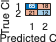

figure();
confusionchart(CMTree_basic, classnamesTree_basic) 


trueLabelsTree_basic = categorical(test_basic{:,"Disease"});
[tTree_basic,aTree_basic] = cMetrics(trueLabelsTree_basic,predictedTree_basic) 

The accuracy of the model is = 66.38%Accuracy = 66.38%

tTree_basic = 4×5 table
              Precision    Recall     Fallout    Specificity      F1   
              _________    _______    _______    ___________    _______

    1          0.75581     0.78313    0.63636      0.36364      0.76923
    2              0.4     0.36364    0.21687      0.78313      0.38095
    Avg        0.57791     0.57338    0.42662      0.57338      0.57509
    WgtAvg     0.65459     0.66379    0.51702      0.48298      0.65877


aTree_basic = 0.6638

## 3: Preprocessing

### 3.1: NaN removal

% after inspecting the dataset, we found that the number of NaNs is small
% enough that we can delete them without it having a negative impact on
% the model 

% Loop through the columns of the table
for column_index = 1:size(tbl, 2)
    % Select the current column
    current_column = tbl(:, column_index);
    % Convert the column to an array
    column_data = table2array(current_column);

    % Check if there are undefined values in the current column
    if iscategorical(column_data)
        nan_indices = isundefined(column_data);
    else
        nan_indices = isnan(column_data);
    end
    
    % Count the number of undefined values in the column
    nan_count = sum(nan_indices);
    
    % Display the "Disease" column if NaN is found in it
    for row_index = 1:size(nan_indices, 1)
        nan_count = nan_count + nan_indices(row_index);
        if nan_indices(row_index) == 1
            tbl.Disease(row_index);
        end
    end
    
    % Display the count of NaN values in the column
    %nan_count
    
    % Remove rows with NaN values from the table
    tbl(nan_indices, :) = [];
end

% Since there are only 7 NaN values (3 non-diseased, 4 diseased), removing
% the NaN rows does not significantly alter the overall distribution.

#### 3.1.1: Storing two version of the dataset: tbl (no NaNs) and tbl_wins (no NaNs and winsorizing)

tbl_wins = tbl; % here we'll apply winsorizing and remove outliers by visual inspection

### 3.2: Handling Outliers 

#### 3.2.1: Removal After Visual Inspection

% these outliers don't have a gaussian distribution, so the boxplot is not
% effective

summary(tbl_wins);

Variables:

    Age: 576×1 double

        Values:

            Min           4   
            Median       45   
            Max          90   

    Gender: 576×1 categorical

        Values:

            Female      139   
            Male        437   

    Total_Bilirubin: 576×1 double

        Values:

            Min         0.4   
            Median        1   
            Max          75   

    Direct_Bilirubin: 576×1 double

        Values:

            Min          0.1  
            Median       0.3  
            Max         19.7  

    Alkaline_Phosphotase: 576×1 double

        Values:

            Min           63  
            Median       208  
            Max         2110  

    Alamine_Aminotransferase: 576×1 double

        Values:

            Min           10  
            Median        35  
            Max         2000  

    Aspartate_Aminotransferase


% by visual inspection, these are the eows we need to remove: 118, 129, 136, 167, 234, 505, 532, 560, 582
out_rows = [118, 129, 136, 167, 234, 505, 532, 560, 582];

for i=1:length(out_rows)
    tbl_wins(i,:) = [];
end

summary(tbl_wins); 

Variables:

    Age: 567×1 double

        Values:

            Min           4   
            Median       45   
            Max          90   

    Gender: 567×1 categorical

        Values:

            Female      137   
            Male        430   

    Total_Bilirubin: 567×1 double

        Values:

            Min         0.4   
            Median        1   
            Max          75   

    Direct_Bilirubin: 567×1 double

        Values:

            Min          0.1  
            Median       0.3  
            Max         19.7  

    Alkaline_Phosphotase: 567×1 double

        Values:

            Min           63  
            Median       208  
            Max         2110  

    Alamine_Aminotransferase: 567×1 double

        Values:

            Min           10  
            Median        35  
            Max         2000  

    Aspartate_Aminotransferase

% the second summary shows no significant changes in the distribution after
% outliers' removal

#### 3.2.2: With Winsorizing

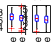

% total proteins and albumin have a gaussian distribution, so the boxplot
% and winsorizing might be effective

contvars= ["Total_Proteins", "Albumin"]; 

figure();
for i=1:length(contvars)
    subplot(1,2,i)
boxplot(eval(strcat("tbl_wins.",contvars(i))),tbl_wins.Gender)
title(contvars(i))
end

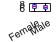


% after looking at the boxplot, the total proteins are the only one out of
% the two features to have some outlier that might be handled using the
% winsorizing technique. 
tbl_wins.Total_Proteins = winsorising(tbl_wins.Total_Proteins);

% boxplot of total proteins after winsorizing.
figure();
boxplot(tbl_wins.Total_Proteins,tbl_wins.Gender)

### 3.3: IT. STEP Adding Features and Examples to Our Imbalanced Dataset

### 3.3.1: IT. STEP Creating a categorical variable from Alanine

% we start with albumin and alamine, which seem to be reliable indicators
% of liver disease. By looking at the distribution, we pick a threshold by
% looking at the tail


% for each element in the tbl_wins, if alamine is below threshold, the
% columns get value "below", "above" otherwise
alamine_threshold = 82

alamine_threshold = 82



% create new column: categorical var with "below" or "above" 
alamine_cat = zeros(height(tbl_wins),1);
for i=1:height(tbl_wins)
    if tbl_wins.Alamine_Aminotransferase(i) >= alamine_threshold
        alamine_cat(i) = 1;  % above threshold
    else 
        alamine_cat(i) = 0; % below threshold
    end

end

alamine_cat = categorical(alamine_cat);

alamine_cat = array2table(alamine_cat, "VariableNames", "AboveAlanineThresh");

% concatenate the two tables to create the new, extended, dataset
tbl_wins_ext = horzcat(tbl_wins, alamine_cat);

### 3.3.2: IT. STEP Creating a categorical variable from Albumin

albumin_threshold = 3.5

albumin_threshold = 3.5000


% create new column: categorical var with "below" or "above" 
albumin_cat = zeros(height(tbl_wins),1);
for i=1:height(tbl_wins)
    if tbl_wins.Albumin(i) >= albumin_threshold
        albumin_cat(i) = 1; % above threshold
    else 
        albumin_cat(i) = 0; % below threshold
    end

end

albumin_cat = categorical(albumin_cat);

albumin_cat = array2table(albumin_cat, "VariableNames", "InsideNormalRange");

tbl_wins_ext = horzcat(tbl_wins_ext, albumin_cat);


## 3.3.3: IT.STEP non-liver patients are in a 1:3 ratio with the liver patients. 

We duplicate the rows of the non-liver patients in an attempt to make the dataset more balanced

not_diseased = tbl_wins_ext(tbl_wins_ext.Disease == '2', :);

not_diseased_dup = repmat(not_diseased, 2, 1);

tbl_wins_ext_dup = [tbl_wins_ext ; not_diseased_dup];

## 4: Trying out different models

### 4.1: Decision Tree on dataset tbl_wins

#### 4.1.1: no NaNs and winsorizing, but no other changes to the dataset

cv_wins = cvpartition(tbl_wins.Disease,"HoldOut",0.2);
train_wins = tbl_wins(training(cv_wins),:);
test_wins = tbl_wins(test(cv_wins),:);

mdlTree_wins = fitctree(train_wins,"Disease")

mdlTree_wins =   ClassificationTree
           PredictorNames: {'Age'  'Gender'  'Total_Bilirubin'  'Direct_Bilirubin'  'Alkaline_Phosphotase'  'Alamine_Aminotransferase'  'Aspartate_Aminotransferase'  'Total_Proteins'  'Albumin'  'Albumin_and_Globulin_Ratio'}
             ResponseName: 'Disease'
    CategoricalPredictors: 2
               ClassNames: [1    2]
           ScoreTransform: 'none'
          NumObservations: 454


  Properties, Methods


predictedTree_wins = predict(mdlTree_wins,test_wins);
[CMTree_wins, classnamesTree_wins] = confusionmat(test_wins.Disease,predictedTree_wins)

CMTree_wins =     63    18
    20    12


classnamesTree_wins = 2×1 categorical array
     1 
     2 


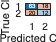

figure();
confusionchart(CMTree_wins, classnamesTree_wins) 

#### 4.1.2: Decision Tree - model evaluation

trueLabels_wins = categorical(test_wins{:,"Disease"});
[tTree_wins,aTree_wins] = cMetrics(trueLabels_wins,predictedTree_wins) 

The accuracy of the model is = 66.37%Accuracy = 66.37%

tTree_wins = 4×5 table
              Precision    Recall     Fallout    Specificity      F1   
              _________    _______    _______    ___________    _______

    1          0.75904     0.77778      0.625        0.375      0.76829
    2              0.4       0.375    0.22222      0.77778       0.3871
    Avg        0.57952     0.57639    0.42361      0.57639      0.57769
    WgtAvg     0.65736     0.66372    0.51094      0.48906      0.66034


aTree_wins = 0.6637

### 4.2: Naive Bayes on dataset tbl_wins

#### 4.2.1: training and testing

mdlNB_wins = fitcnb(train_wins,"Disease")

mdlNB_wins =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Gender'  'Total_Bilirubin'  'Direct_Bilirubin'  'Alkaline_Phosphotase'  'Alamine_Aminotransferase'  'Aspartate_Aminotransferase'  'Total_Proteins'  'Albumin'  'Albumin_and_Globulin_Ratio'}
              ResponseName: 'Disease'
     CategoricalPredictors: 2
                ClassNames: [1    2]
            ScoreTransform: 'none'
           NumObservations: 454
         DistributionNames: {'normal'  'mvmn'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×10 cell}
         CategoricalLevels: {[]  [2×1 double]  []  []  []  []  []  []  []  []}


  Properties, Methods


predictedNB_wins = predict(mdlNB_wins,test_wins);
[CMNB_wins, classnamesNB_wins] = confusionmat(test_wins.Disease,predictedNB_wins)

CMNB_wins =     33    48
     2    30


classnamesNB_wins = 2×1 categorical array
     1 
     2 


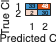

confusionchart(CMNB_wins, classnamesNB_wins) 

#### 4.2.2: model evaluation

trueLabelsNB_wins = categorical(test_wins{:,"Disease"});
[tNB_wins,aNB_wins] = cMetrics(trueLabelsNB_wins,predictedNB_wins) 

The accuracy of the model is = 55.75%Accuracy = 55.75%

tNB_wins = 4×5 table
              Precision    Recall     Fallout    Specificity      F1   
              _________    _______    _______    ___________    _______

    1          0.94286     0.40741     0.0625       0.9375      0.56897
    2          0.38462      0.9375    0.59259      0.40741      0.54545
    Avg        0.66374     0.67245    0.32755      0.67245      0.55721
    WgtAvg     0.78477     0.55752    0.21261      0.78739      0.56231


aNB_wins = 0.5575

## 5: IT.STEP Using the new dataset

% creating the test and train partitions on the dataset that has:
% - some outliers removed, others handled with winsorizing
% - new categorical variables for alanine and albumin
% - duplicated rows for non-liver patients
cv_ext = cvpartition(tbl_wins_ext_dup.Disease,"HoldOut",0.2);
train_ext = tbl_wins_ext_dup(training(cv_ext),:);
test_ext = tbl_wins_ext_dup(test(cv_ext),:);

### 5.1: IT.STEP Decision Tree

#### 5.1.1 Training

mdlTree_ext = fitctree(train_ext,"Disease")

mdlTree_ext =   ClassificationTree
           PredictorNames: {1×12 cell}
             ResponseName: 'Disease'
    CategoricalPredictors: [2 11 12]
               ClassNames: [1    2]
           ScoreTransform: 'none'
          NumObservations: 713


  Properties, Methods


predictedTree_ext = predict(mdlTree_ext,test_ext);
[CMTree_ext, classnamesTree_ext] = confusionmat(test_ext.Disease,predictedTree_ext)

CMTree_ext =     56    25
     7    90


classnamesTree_ext = 2×1 categorical array
     1 
     2 


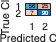

confusionchart(CMTree_ext, classnamesTree_ext) 

#### 5.1.2: Decision Tree  - model evaluation

trueLabelsTree_ext = categorical(test_ext{:,"Disease"});
[tTree_ext,aTree_ext] = cMetrics(trueLabelsTree_ext,predictedTree_ext) 

The accuracy of the model is = 82.02%Accuracy = 82.02%

tTree_ext = 4×5 table
              Precision    Recall     Fallout     Specificity      F1   
              _________    _______    ________    ___________    _______

    1          0.88889     0.69136    0.072165      0.92784      0.77778
    2          0.78261     0.92784     0.30864      0.69136      0.84906
    Avg        0.83575      0.8096      0.1904       0.8096      0.81342
    WgtAvg     0.83097     0.82022     0.20103      0.79897      0.81662


aTree_ext = 0.8202

### 5.2: IT. STEP kNN

% kNN wants a dataset that doesn't have a mix of categorical and numerical
% variables (which is our case: Gender, InsideNormalRange,
% AboveAlamineThreshold are all categorical variables)

% we crate a new table with all numerical variables (categorical are
% transformed to numerical using dummyvar)

% this same dataset will be used for the regression task

tbl_all_numeric = tbl_wins_ext_dup;
gender_numeric = dummyvar(tbl_wins_ext_dup.Gender);
tbl_all_numeric.Gender = gender_numeric(:,1);

alThresh_numeric = dummyvar(tbl_wins_ext_dup.AboveAlanineThresh);
tbl_all_numeric.AboveAlanineThresh = alThresh_numeric(:,1);

normalRange_numeric = dummyvar(tbl_wins_ext_dup.InsideNormalRange);
tbl_all_numeric.InsideNormalRange = normalRange_numeric(:,1);

#### 5.2.1: cvpartition

cv_num = cvpartition(tbl_all_numeric.Disease,"HoldOut",0.2);
train_num = tbl_all_numeric(training(cv_num),:);
test_num = tbl_all_numeric(test(cv_num),:);

#### 5.2.2 training and testing

mdlKNN =   ClassificationKNN
           PredictorNames: {1×12 cell}
             ResponseName: 'Disease'
    CategoricalPredictors: []
               ClassNames: [1    2]
           ScoreTransform: 'none'
          NumObservations: 713
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


CMKNN =     58    23
     0    97


classnamesKNN = 2×1 categorical array
     1 
     2 


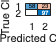

% Note: We chose k=1 for the k-NN algorithm because the feature values for diseased and non-diseased patients are very similar. 
% Moreover, since diseased patients are more frequent, a higher k value would often favor the diseased class, which is not desirable.
% This choice helps to better distinguish between the classes despite the imbalance and similarity in feature values.
mdlKNN = fitcknn(train_num, "Disease", "NumNeighbors", 1);
predictedKNN = predict(mdlKNN, test_num);
[CMKNN, classnamesKNN] = confusionmat(test_num.Disease, predictedKNN);
confusionchart(CMKNN, classnamesKNN);

#### 5.2.3: knn model evaluation

trueLabelsKNN = categorical(test_num{:,"Disease"});
[tKNN,aKNn] = cMetrics(trueLabelsKNN,predictedKNN) 

The accuracy of the model is = 87.08%Accuracy = 87.08%

tKNN = 4×5 table
              Precision    Recall     Fallout    Specificity      F1   
              _________    _______    _______    ___________    _______

    1                1     0.71605          0            1      0.83453
    2          0.80833           1    0.28395      0.71605      0.89401
    Avg        0.90417     0.85802    0.14198      0.85802      0.86427
    WgtAvg     0.89555     0.87079    0.15474      0.84526      0.86694


aKNn = 0.8708

### 5.3: IT. STEP Naive Bayes

#### 5.3.1: training and testing

mdlNB_ext = fitcnb(train_ext,"Disease")

mdlNB_ext =   ClassificationNaiveBayes
            PredictorNames: {1×12 cell}
              ResponseName: 'Disease'
     CategoricalPredictors: [2 11 12]
                ClassNames: [1    2]
            ScoreTransform: 'none'
           NumObservations: 713
         DistributionNames: {'normal'  'mvmn'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'mvmn'  'mvmn'}
    DistributionParameters: {2×12 cell}
         CategoricalLevels: {[]  [2×1 double]  []  []  []  []  []  []  []  []  [2×1 double]  [2×1 double]}


  Properties, Methods


predictedNB_ext = predict(mdlNB_ext,test_ext);
[CMNB_ext, classnamesNB_ext] = confusionmat(test_ext.Disease,predictedNB_ext)

CMNB_ext =     36    45
     3    94


classnamesNB_ext = 2×1 categorical array
     1 
     2 


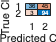

confusionchart(CMNB_ext, classnamesNB_ext) 

#### 5.3.2: model evaluation

trueLabelsNB_ext = categorical(test_ext{:,"Disease"});
[tNB_ext,aNB_ext] = cMetrics(trueLabelsNB_ext,predictedNB_ext)

The accuracy of the model is = 73.03%Accuracy = 73.03%

tNB_ext = 4×5 table
              Precision    Recall     Fallout     Specificity      F1   
              _________    _______    ________    ___________    _______

    1          0.92308     0.44444    0.030928      0.96907          0.6
    2          0.67626     0.96907     0.55556      0.44444      0.79661
    Avg        0.79967     0.70676     0.29324      0.70676      0.69831
    WgtAvg     0.78858     0.73034     0.31682      0.68318      0.70714


aNB_ext = 0.7303

## Comments on Results

% The best model seems to be Decision Tree, and the addition of categorical
% variables, along with the duplicated rows for non-liver patients seem to
% improve the model significantly (from roughly 68% to 83%).

## 6: Side Question 2 - Regression to predict Total Proteins value

### 6.0: creating the training and test sets

% we're using the same dataset we used for the classification step (with
% wins, added features and duplicates of nonliver patients) of knn.
cv_reg_num = cvpartition(tbl_all_numeric.Total_Proteins,"HoldOut",0.2, 'stratify', false);
train_reg_num = tbl_all_numeric(training(cv_reg_num),:);
test_reg_num = tbl_all_numeric(test(cv_reg_num),:);

### 6.1: Neural Net 

% all & numeric
MdlNet_reg = fitrnet(train_reg_num, "Total_Proteins");
testMSE = loss(MdlNet_reg,test_reg_num,"Total_Proteins")

testMSE = 0.1181

### 6.2: SVM

MdlSVM_reg = fitrsvm(train_reg_num, "Total_Proteins");
testMSE_SVM = loss(MdlSVM_reg, test_reg_num, "Total_Proteins")

testMSE_SVM = 5.2346

### 6.3: Decision Tree

MdlTree_reg = fitrtree(train_reg_num, "Total_Proteins");
testMSE_Tree = loss(MdlTree_reg, test_reg_num, "Total_Proteins")

testMSE_Tree = 0.0969